Express the given second-order ODE as a pair of first-order ODEs:

Let $y_1 =x$, and $y_2 =\frac{{\mathrm{dy}}_2 }{\mathrm{dt}}\to \frac{{\mathrm{dy}}_2 }{\mathrm{dt}}=\frac{{d^2 y}_1 }{{\mathrm{dt}}^2 }=\frac{d^2 x}{{\mathrm{dt}}^2 }$, then we have the following ODE system: 


$$\begin{array}{l}
\frac{{\mathrm{dy}}_1 }{\mathrm{dt}}=y_2 \\
\frac{{\mathrm{dy}}_2 }{\mathrm{dt}}=\frac{1}{m}*\left(\mathrm{Pcos}\left(\mathrm{wt}\right)-{\mathrm{cy}}_2 -k_1 y_1 -k_3 y_1^3 \right)
\end{array}$$


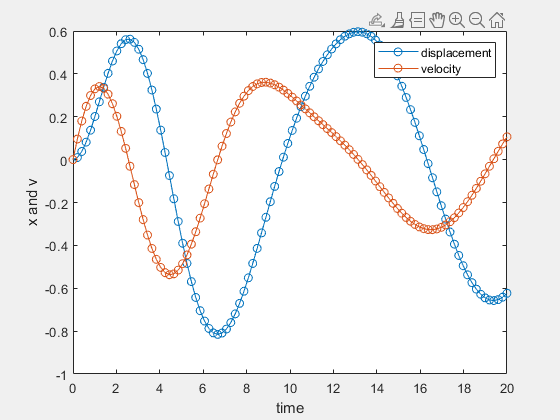


init=[0 0]; % initial condition
t=linspace(0,20); 
ode45(@myfunc,t,init);
legend('displacement','velocity')
xlabel('time')
ylabel('x and v')

function [dydt] = myfunc(t,y)
m=1;c=0.4;P=0.5;w=0.5;k1=1;k3=0;
dydt = zeros(2,1);
dydt(1) = y(2);
dydt(2) = (1/m)*(P*cos(w*t)-c*y(2)-k1*y(1)-k3*y(1)^3);
end